# simpler case PEC reflective surfecse

## parameters


theta_in = 10*pi/180;       % rad
theta_out= 70*pi/180;       % rad

lambda = 1;                 % lambda
Lambda = lambda/abs(sin(theta_in)-sin(theta_out));  % lambda

eta = 1;                    % eta
k = 2*pi/lambda;              % 1/lambda
E0 = 1;                     % E0

NumLayers = 2;

phi = -k*Lambda*sin(theta_in);  %rad

reff = 6.35e-4;         % lambda for f = 10 GHz
MaxSizeLayer=lambda;

optimTimes = 50;
Norder=100;

## optimization

optimiztionFunc=@(x)optimiztionFunction(x,Lambda,k,eta,E0,reff,phi,theta_in,NumLayers,Norder);
b = [Lambda*ones(1,NumLayers) zeros(1,NumLayers) -MaxSizeLayer*ones(1,NumLayers) zeros(1,NumLayers)];
A = [eye(NumLayers), zeros(NumLayers); -1*eye(NumLayers), zeros(NumLayers); zeros(NumLayers) ,-1*eye(NumLayers); zeros(NumLayers) ,eye(NumLayers)];
BestResults = inf;
DsResult = zeros(1,NumLayers); %[Ds Hs]
HsResuts = zeros(1,NumLayers);
numOfGoodResults=0;
options = optimoptions('fmincon','Display','off');
for optimiztionIndex = 1:optimTimes
    disp(['itteration ' num2str(optimiztionIndex) ' out of ' num2str(optimTimes)])
    x0=[Lambda*rand(1,NumLayers),MaxSizeLayer*rand(1,NumLayers)]; %[Ds Hs]
    [x,optimValue] = fmincon(optimiztionFunc,x0,A,b,[],[],[],[],[],options);
    Ds = transpose(x(1:NumLayers));
    Hs = transpose(x(NumLayers+1:end));
    [Zs,Is] = calcZm(Ds,Hs,eta,k,Lambda,E0,phi,theta_in,Norder,reff,NumLayers);
    if(imag(Zs)<0)
        numOfGoodResults = numOfGoodResults + 1;
        if BestResults > optimValue
            DsResult = Ds;
            HsResuts = Hs;
            BestResults = optimValue;
            ZsResults = Zs;
            IsResults = Is;
        end
    end
end

itteration 1 out of 50
itteration 2 out of 50
itteration 3 out of 50


itteration 4 out of 50
itteration 5 out of 50
itteration 6 out of 50
itteration 7 out of 50
itteration 8 out of 50
itteration 9 out of 50
itteration 10 out of 50
itteration 11 out of 50
itteration 12 out of 50
itteration 13 out of 50
itteration 14 out of 50
itteration 15 out of 50
itteration 16 out of 50
itteration 17 out of 50
itteration 18 out of 50
itteration 19 out of 50
itteration 20 out of 50
itteration 21 out of 50
itteration 22 out of 50
itteration 23 out of 50
itteration 24 out of 50
itteration 25 out of 50
itteration 26 out of 50
itteration 27 out of 50
itteration 28 out of 50
itteration 29 out of 50
itteration 30 out of 50
itteration 31 out of 50
itteration 32 out of 50
itteration 33 out of 50
itteration 34 out of 50
itteration 35 out of 50
itteration 36 out of 50
itteration 37 out of 50
itteration 38 out of 50
itteration 39 out of 50
itteration 40 out of 50
itteration 41 out of 50
itteration 42 out of 50
itteration 43 out of 50
itteration 44 out of 50
itteration 45 out of 5

## plotting

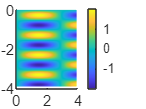

Nplot = 100;
y = linspace(0,Lambda*3,Nplot);
z = -linspace(0,Lambda*3,Nplot)';

[Einc, Egen] = calcElectricFields(y,z,DsResult,HsResuts,IsResults,Lambda,k,eta,E0,phi,theta_in,NumLayers,Norder);
figure;
hold on;
s = surf(y,z,real(Einc));
s.EdgeColor = "none"; colorbar;

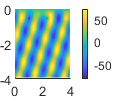


figure;
hold on;
s = surf(y,z,real(Egen));
s.EdgeColor = "none"; colorbar;

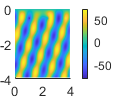


figure;
hold on;
s = surf(y,z,real(Einc+Egen));
s.EdgeColor = "none"; colorbar;

## functions

### calculates impadances

function [Zs,Is] = calcZm(Ds,Hs,eta,k,Lambda,E0,phi,theta_in,Norder,reff,NumLayers)
    [Is] = calcCurrnetsIm(Ds,Hs,eta,k,Lambda,E0,phi);
    E_wave = E0*(exp(-1j*k*(sin(theta_in)*Ds+cos(theta_in).*Hs))-exp(-1j*k*(sin(theta_in)*Ds-cos(theta_in).*Hs)));
    Zs = zeros(NumLayers,1);
    for Mindex = 1:NumLayers
        ReflectionLayerSum = calcReflectionLayerSum(Hs,k,Lambda,phi,Norder,Mindex);
        SelfLayerSum = calcSelfLayerSum(k,Lambda,phi,reff,Norder);
        RestLayersSum = calcRestLayersSum(Ds,Hs,Is,k,Lambda,phi,Norder,Mindex,NumLayers);
        
        Zs(Mindex) = E_wave(Mindex)+k*eta/(2*Lambda)*(SelfLayerSum+ReflectionLayerSum)-k*eta/(2*Lambda*Is(Mindex))*RestLayersSum;
    end

end

### calculates sums

function [RestLayersSum] = calcRestLayersSum(Ds,Hs,Is,k,Lambda,phi,Norder,Mindex,NumLayers)
    RestLayersSum = 0;
    Nvector = (-Norder:Norder);
    [Alphas,Betas] = calcAlphasBetas(k,Lambda,phi,Nvector);
    for m = [(1:Mindex-1) (Mindex+1:NumLayers)]
        RestLayersSum = RestLayersSum + Is(m)*sum(exp(-1j*Alphas.*(Ds(Mindex)-Ds(m)))./Betas.*...
            (exp(-1j*Betas.*abs(Hs(Mindex)-Hs(m)))-exp(-1j*Betas.*abs(Hs(Mindex)+Hs(m)))));
    end
end

function [SelfLayerSum] = calcSelfLayerSum(k,Lambda,phi,reff,Norder)
    Nvector = [(-Norder:-1) (1:Norder)];
    [~,Betas] = calcAlphasBetas(k,Lambda,phi,Nvector);
    [~,beta0] = calcAlphasBetas(k,Lambda,phi,0);
    SelfLayerSum = 1j*Lambda/pi*log(2*pi*reff/Lambda)-1/beta0-sum(1./Betas-Lambda./(2*pi*abs(Nvector)));
end

function [ReflectionLayerSum] = calcReflectionLayerSum(Hs,k,Lambda,phi,Norder,Mindex)
    Nvector = (-Norder:Norder);
    [~,Betas] = calcAlphasBetas(k,Lambda,phi,Nvector);
    ReflectionLayerSum = sum(exp(-2j*Betas*Hs(Mindex))./Betas);
end


### calculates currents

function [Im] = calcCurrnetsIm(Ds,Hs,eta,k,Lambda,E0,phi)
    % Hs & Ds must be col vectors
    IndexVector = [-1 0];
    [Alphas,Betas] = calcAlphasBetas(k,Lambda,phi,IndexVector);
    Matrix = 1j*k*eta/Lambda*(exp(1j*Alphas.*Ds)./Betas.*sin(Betas.*Hs));
    Vector = E0*[0 ; 1];
    Im = Matrix\Vector;
end

### calculates Alphas and betas

function [Alphas,Betas] = calcAlphasBetas(k,Lambda,phi,IndexVector)
    Alphas = (2*pi*IndexVector-phi)/Lambda;
    Betas  = conj(sqrt(k^2-Alphas.^2));
end

### optimization function

function Optimvalue = optimiztionFunction(x,Lambda,k,eta,E0,reff,phi,theta_in,NumLayers,Norder)
    Ds = transpose(x(1:NumLayers));
    Hs = transpose(x(NumLayers+1:end));
    [Zs,Is] = calcZm(Ds,Hs,eta,k,Lambda,E0,phi,theta_in,Norder,reff,NumLayers);
    %Optimvalue = eta/2*sum(abs(real(Zs).*abs(Is).^2),'all');
    Optimvalue = sum(abs(real(Zs)),'all');
end

### calculates the electric field in space

function [Einc, Egen] = calcElectricFields(yVec,zVec,Ds,Hs,Is,Lambda,k,eta,E0,phi,theta_in,NumLayers,Norder)
    % yVec is a row vec
    % zVec is a cul vec
    %
    Einc = -2j*E0*exp(-1j*(k*sin(theta_in)*yVec)).*sin(k*cos(theta_in)*zVec);
    
    newIs = reshape(Is,[1 1 NumLayers]);
    newDs = reshape(Ds,[1 1 NumLayers]);
    newHs = reshape(Hs,[1 1 NumLayers]);
    Nvec = (-Norder:Norder);
    [Alphas,Betas] = calcAlphasBetas(k,Lambda,phi,Nvec);
    sumValue = zeros(length(zVec),length(yVec));
    for Nindex = Nvec
        alpha=Alphas(Nindex+Norder+1);
        beta=Betas(Nindex+Norder+1);
        sumValue = sumValue+sum(newIs.*exp(-1j*alpha*(yVec-newDs))...
            .*(exp(-1j*beta*abs(zVec-newHs))-exp(-1j*beta*abs(zVec+newHs))),3)/beta;
    end
    Egen = -k*eta/(2*Lambda)*sumValue;

end